dataDir = 'PlantVillage'; 
imds = imageDatastore(dataDir, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

disp('✅ Đã nạp dữ liệu thành công!');

✅ Đã nạp dữ liệu thành công!


disp(['Tổng số lượng ảnh trong Dataset: ', num2str(numel(imds.Files))]);

Tổng số lượng ảnh trong Dataset: 20638


disp(['Tổng số loại bệnh (Classes): ', num2str(numel(categories(imds.Labels)))]);

Tổng số loại bệnh (Classes): 15


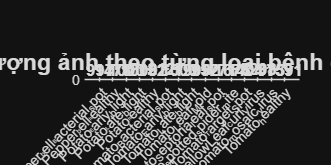

labelCounts = countEachLabel(imds); 

figure('Name', 'Phân bố Dữ liệu', 'Position', [100, 100, 1000, 500]);

b = bar(labelCounts.Count, 'FaceColor', [0.2 0.6 0.5], 'EdgeColor', 'none');

xtips = b.XEndPoints;
ytips = b.YEndPoints; 
labels = string(b.YData); 
text(xtips, ytips, labels, 'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'bottom', 'FontSize', 10, 'FontWeight', 'bold');

set(gca, 'XTickLabel', labelCounts.Label, 'XTick', 1:height(labelCounts));
xtickangle(45); 
title('Thống kê số lượng ảnh theo từng loại bệnh (Class Distribution)', 'FontSize', 14);
ylabel('Số lượng ảnh');
xlabel('Tên loại bệnh');
grid on;

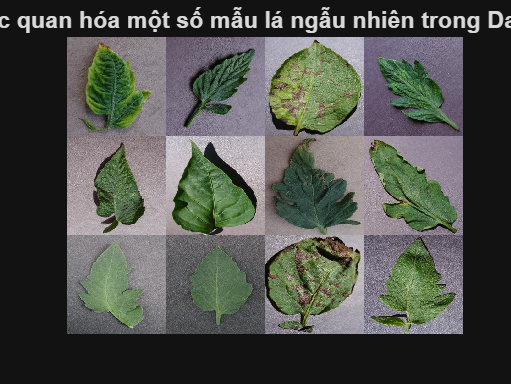

numImagesToView = 12; 
idx = randperm(numel(imds.Files), numImagesToView); 

figure('Name', 'Sample Images', 'Position', [150, 150, 800, 600]);
montage(imds.Files(idx));
title('Trực quan hóa một số mẫu lá ngẫu nhiên trong Dataset', 'FontSize', 14);

sampleImg = readimage(imds, 1);
[rows, cols, channels] = size(sampleImg);
disp('--- Thông số kích thước ảnh mẫu ---');

--- Thông số kích thước ảnh mẫu ---


disp(['Chiều cao (Rows): ', num2str(rows), ' pixels']);

Chiều cao (Rows): 256 pixels


disp(['Chiều rộng (Cols): ', num2str(cols), ' pixels']);

Chiều rộng (Cols): 256 pixels


disp(['Số kênh màu (Channels): ', num2str(channels), ' (3 có nghĩa là ảnh màu RGB)']);

Số kênh màu (Channels): 3 (3 có nghĩa là ảnh màu RGB)


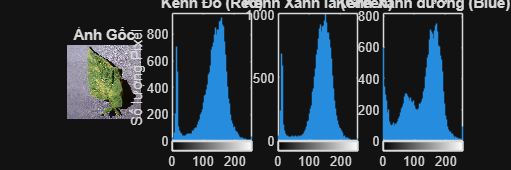

img = readimage(imds, randi(numel(imds.Files)));

figure('Name', 'Phân tích Histogram RGB', 'Position', [200, 200, 1200, 400]);

% Hiển thị ảnh gốc
subplot(1, 4, 1);
imshow(img);
title('Ảnh Gốc');

% Tách 3 kênh màu R, G, B
R = img(:, :, 1);
G = img(:, :, 2);
B = img(:, :, 3);

% Vẽ biểu đồ phân bố cho từng kênh
subplot(1, 4, 2);
imhist(R); title('Kênh Đỏ (Red)');
ylabel('Số lượng Pixel');

subplot(1, 4, 3);
imhist(G); title('Kênh Xanh lá (Green)');

subplot(1, 4, 4);
imhist(B); title('Kênh Xanh dương (Blue)');

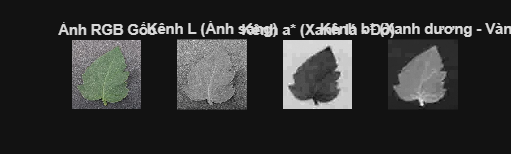

lab_img = rgb2lab(img);
L = lab_img(:, :, 1);
a = lab_img(:, :, 2);
b = lab_img(:, :, 3);

figure('Name', 'Không gian màu L*a*b*', 'Position', [250, 250, 1000, 300]);

subplot(1, 4, 1); imshow(img); title('Ảnh RGB Gốc');
subplot(1, 4, 2); imshow(L, []); title('Kênh L (Ánh sáng)');
subplot(1, 4, 3); imshow(a, []); title('Kênh a* (Xanh lá - Đỏ)');
subplot(1, 4, 4); imshow(b, []); title('Kênh b* (Xanh dương - Vàng)');

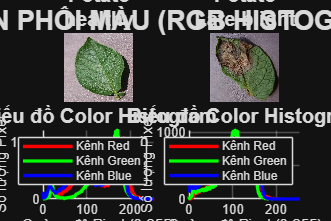

plant_name = 'Potato'; 

% 1. Lọc tìm các loại bệnh thuộc về cây được chọn
all_labels = string(unique(imds.Labels));
plant_labels = all_labels(startsWith(all_labels, plant_name, 'IgnoreCase', true));

healthy_classes = plant_labels(contains(lower(plant_labels), 'healthy'));
diseased_classes = plant_labels(~contains(lower(plant_labels), 'healthy'));

if isempty(healthy_classes) || isempty(diseased_classes)
    disp(['⚠️ Không tìm thấy đủ cặp Khỏe mạnh và Nhiễm bệnh cho cây: ', plant_name]);
else
    target_healthy = healthy_classes(1);
    target_diseased = diseased_classes(randi(length(diseased_classes)));

    classes_to_plot = [target_healthy, target_diseased];

    figure('Name', sprintf('SO SÁNH MÀU SẮC: %s', upper(plant_name)), 'Position', [150, 150, 1200, 800]);
    sgtitle(sprintf('SO SÁNH PHÂN PHỐI MÀU (RGB HISTOGRAM): %s', upper(plant_name)), 'FontSize', 16, 'FontWeight', 'bold');

    for i = 1:2
        class_name = classes_to_plot(i);

        idx_files = find(imds.Labels == class_name);
        random_idx = idx_files(randi(length(idx_files))); 
        img = imread(imds.Files{random_idx});

        % --- DÒNG 0 (HÀNG TRÊN): HIỂN THỊ ẢNH ---
        subplot(2, 2, i);
        imshow(img);

        short_title = strrep(class_name, '___', newline); 
        short_title = strrep(short_title, '_', ' ');
        if i == 1
            prefix = '🌿 Khỏe mạnh (Healthy)';
        else
            prefix = '🍂 Nhiễm bệnh (Diseased)';
        end
        title({prefix, char(short_title)}, 'FontSize', 12, 'FontWeight', 'bold', 'Interpreter', 'none');

        % --- DÒNG 1 (HÀNG DƯỚI): VẼ HISTOGRAM RGB ---
        subplot(2, 2, i + 2);
        hold on;

        % Tính tần suất pixel của 3 kênh R, G, B
        [countsR, x] = imhist(img(:,:,1));
        [countsG, ~] = imhist(img(:,:,2));
        [countsB, ~] = imhist(img(:,:,3));

        % Vẽ các đường đồ thị
        plot(x, countsR, 'r', 'LineWidth', 2, 'DisplayName', 'Kênh Red');
        plot(x, countsG, 'g', 'LineWidth', 2, 'DisplayName', 'Kênh Green');
        plot(x, countsB, 'b', 'LineWidth', 2, 'DisplayName', 'Kênh Blue');

        % Trang trí lưới, trục, chú thích
        xlim([0 255]);
        title('Biểu đồ Color Histogram', 'FontSize', 12);
        xlabel('Cường độ Pixel (0-255)');
        ylabel('Số lượng Pixel');
        grid on;
        legend('show', 'Location', 'northeast');
        hold off;
    end
end